**I. Manipulação de Espetro de Sinais**

**Exercício 01**

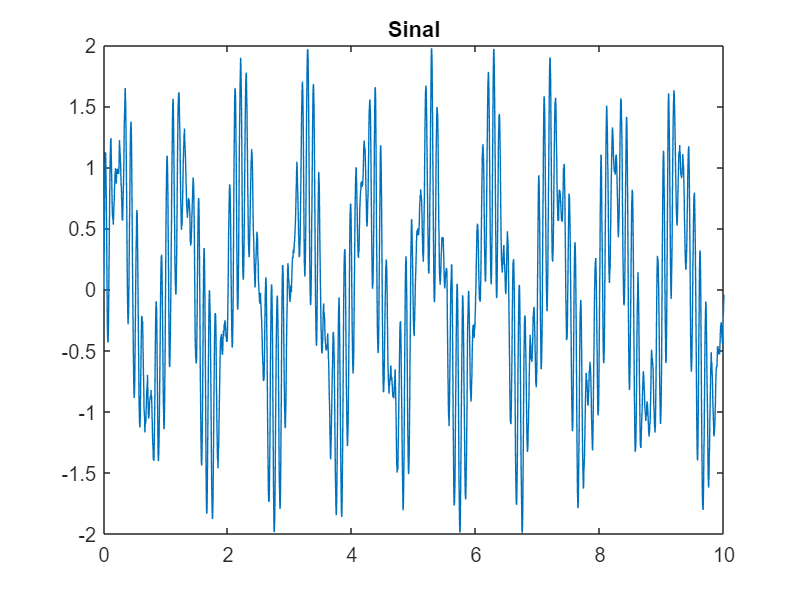

N = 10000;
Ta = 0.001;
Fa = 1/Ta;

[x,t] = GeraSinal(N,Ta);

**Exercício 02**

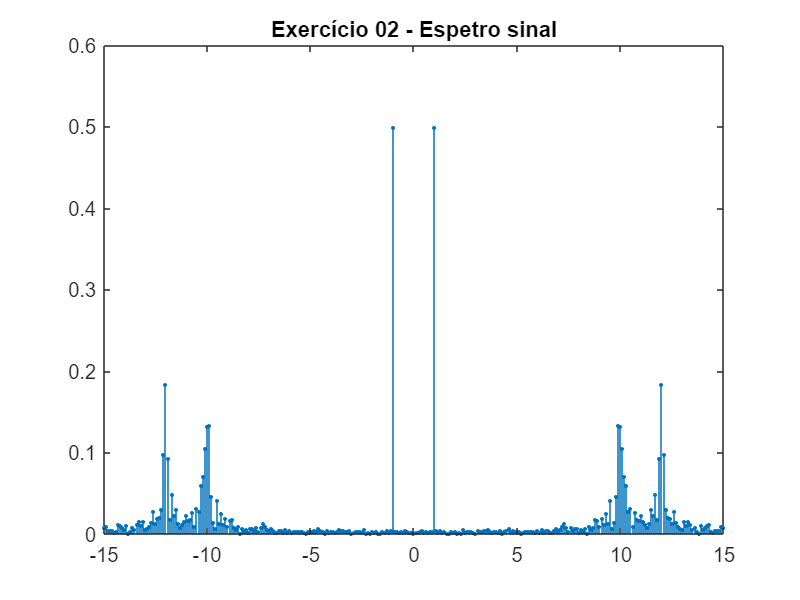

[X,f] = Espetro(x,Ta);

figure;
stem(f,abs(X),".");
axis([-15 15 0 0.6]);
title("Exercício 02 - Espetro sinal");

**Exercício 03**

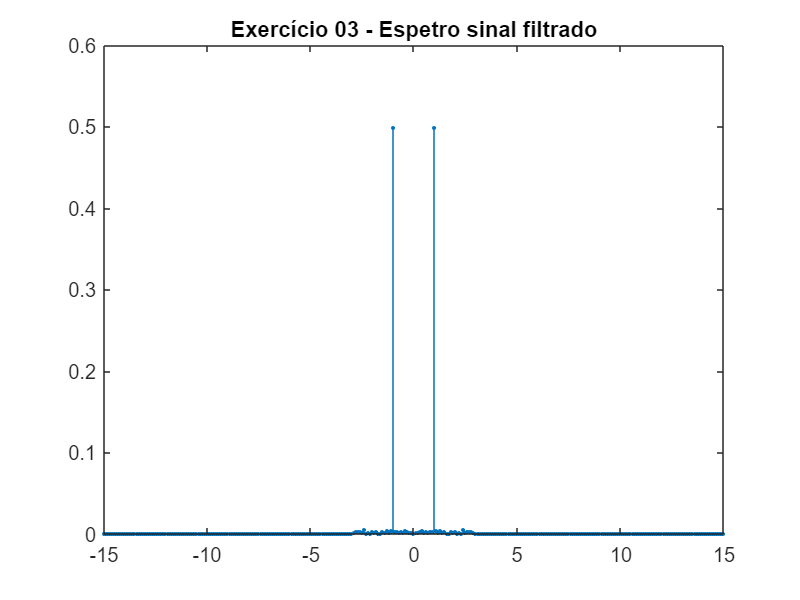

filtro_s = abs(f) < 3;

Y = X.*filtro_s;

figure;
stem(f,abs(Y),".");
axis([-15 15 0 0.6]);
title("Exercício 03 - Espetro sinal filtrado");

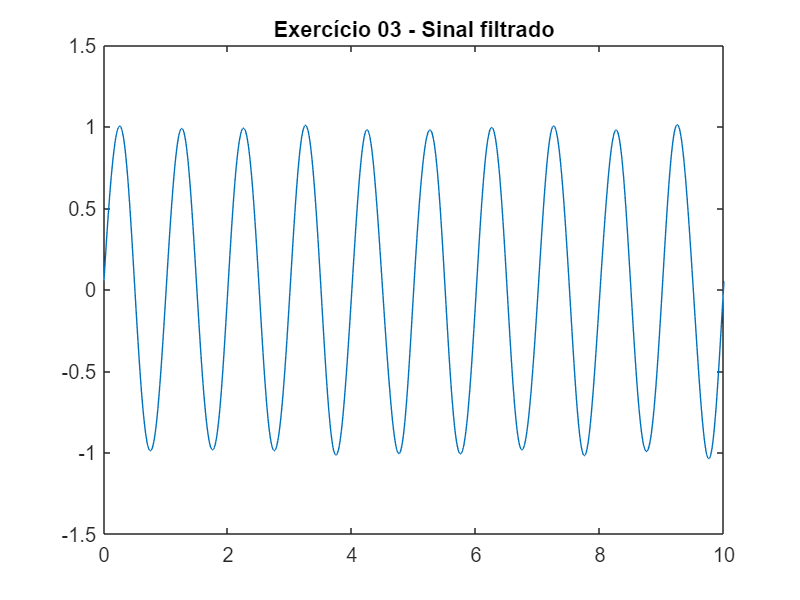


y = Reconstroi(Y);

figure;
plot(t,y);
title("Exercício 03 - Sinal filtrado");

**Exercício 04**

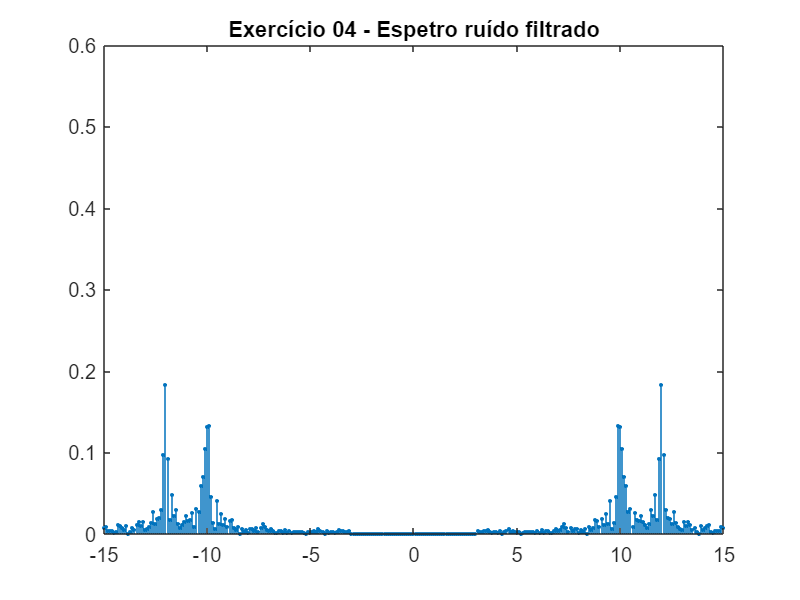

filtro_r = ~filtro_s;

R = X.*filtro_r;

stem(f,abs(R),".");
axis([-15 15 0 0.6]);
title("Exercício 04 - Espetro ruído filtrado");

**Exercício 05**